# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

[INFO]: Read 1 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 2 assets; parsed up to line 12


thisR.set('light','all','delete');

The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

thisLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',thisLight, 'add');
thisR.set('light',thisLight.name,'specscale',0.5);
thisR.set('light',thisLight.name,'spd',[0.5 0.4 0.2]);

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera, so that we are effectively rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

scene = piRender(thisR);

[INFO]: Render Locally.
[INFO]: Uploading data:
[INFO]: Sent 1277 bytes  received 380 bytes  1104.67 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-wandell6876 sh -c " pbrt  --gpu  --outfile /home/wandell/ISETRemoteRender/sphere/renderings/sphere.exr /home/wandell/ISETRemoteRender/sphere/sphere.pbrt "
[INFO]: Rendered remotely in: 1.87 sec
[INFO]: Downloading data:
[INFO]: Sent 2474 bytes  received 48504 bytes  101956.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/sphere.exr


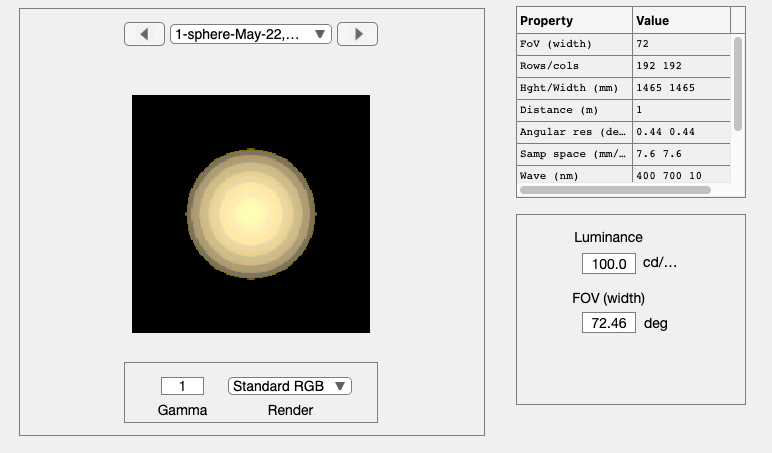

sceneWindow(scene);

[scene, result] = piRender(thisR);

[INFO]: Render Locally.
[INFO]: Uploading data:
[INFO]: Sent 302 bytes  received 20 bytes  644.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-wandell6876 sh -c " pbrt  --gpu  --outfile /home/wandell/ISETRemoteRender/sphere/renderings/sphere.exr /home/wandell/ISETRemoteRender/sphere/sphere.pbrt "
[INFO]: Rendered remotely in: 2.08 sec
[INFO]: Downloading data:
[INFO]: Sent 494 bytes  received 380 bytes  1748.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/sphere.exr


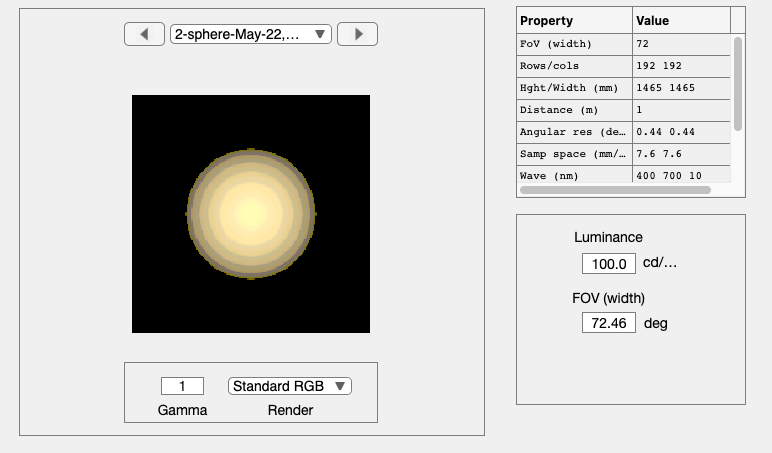

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

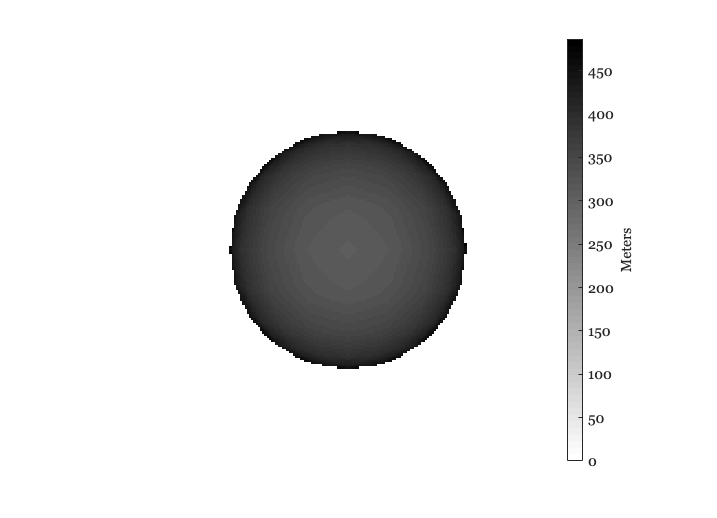

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

% Remove the light we added
thisR.set('light',thisLight.name, 'delete');

% Create a new version with a different color temperature
thisLight = piLightCreate('distant','type','distant',  'spd', 9000);
thisR.set('light',thisLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

[INFO]: Uploading data:
[INFO]: Sent 1266 bytes  received 380 bytes  3292.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-wandell6876 sh -c " pbrt  --gpu  --outfile /home/wandell/ISETRemoteRender/sphere/renderings/sphere.exr /home/wandell/ISETRemoteRender/sphere/sphere.pbrt "
[INFO]: Rendered remotely in: 2.02 sec
[INFO]: Downloading data:
[INFO]: Sent 494 bytes  received 278901 bytes  558790.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/sphere.exr


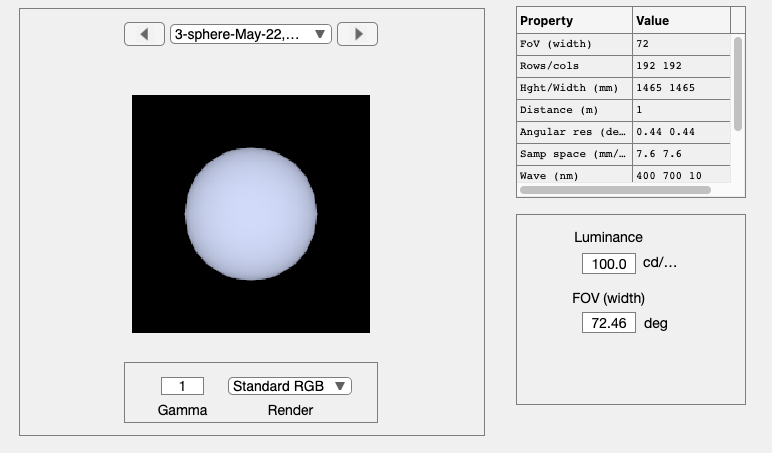

piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
% fname = fullfile(piRootPath,'data','scenes','teapot-set','TeaTime-converted.pbrt');
fname = fullfile(piRootPath,'data','scenes','web','SimpleScene','SimpleScene.pbrt');
thisR  = piRead(fname);

[INFO]: Read 7 materials and 1 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 9 assets; parsed up to line 103


Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);

Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
% thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');


----- Summary of recipe: recipe

                   index      material          positions (m)             sizes (m)      
                   _____    _____________    ____________________    ____________________

    figure_3m_O     21      {'uber_blue'}    {'0.00 0.50 -12.03'}    {'1.02 1.00 0.17'  }
    figure_6m_O     24      {'uber'     }    {'1.00 0.50 -9.00' }    {'1.02 1.00 0.17'  }
    Sphere_O        27      {'BODY'     }    {'3.63 1.14 8.43'  }    {'2.00 2.00 2.00'  }
    glass_O         30      {'GLASS'    }    {'0.18 0.91 5.79'  }    {'8.00 2.00 0.00'  }
    mirror_O        33      {'mirror'   }    {'0.47 4.30 3.01'  }    {'13.42 3.51 16.17'}
    Plane_O         37      {'Material' }    {'0.00 0.00 0.00'  }    {'50.00 0.00 50.00'}

From [

## Add a light

[INFO]: Uploading data:
[INFO]: Sent 4640 bytes  received 4646 bytes  6190.67 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-wandell6876 sh -c " pbrt  --gpu  --outfile /home/wandell/ISETRemoteRender/SimpleScene/renderings/SimpleScene.exr /home/wandell/ISETRemoteRender/SimpleScene/SimpleScene.pbrt "
[INFO]: Rendered remotely in: 2.24 sec
[INFO]: Downloading data:
[INFO]: Sent 11600 bytes  received 930 bytes  8353.33 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/SimpleScene.exr


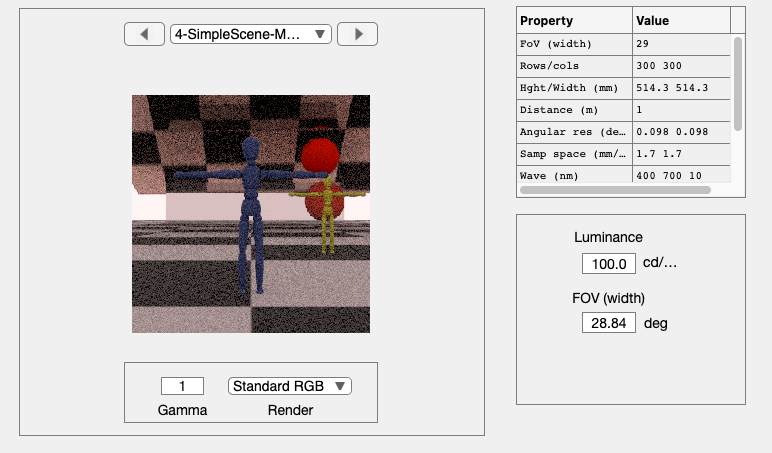

thisR.set('lights','all','delete');
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

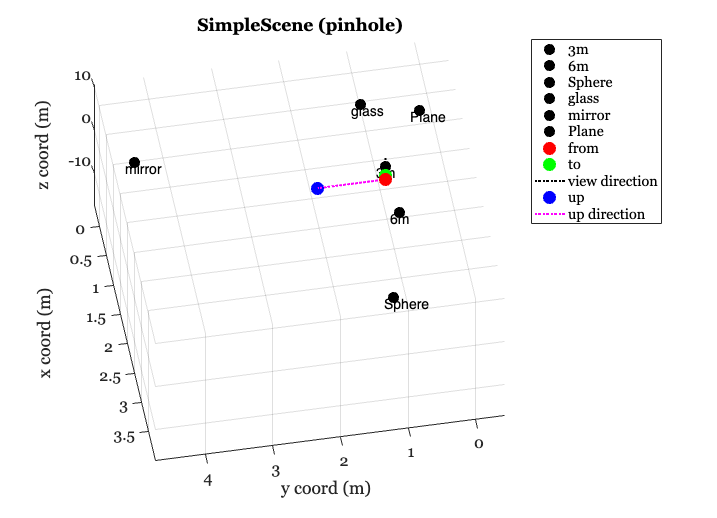

piAssetGeometry(thisR);view(-80,-65);